# Examples for using the `secant_method` function.

Copyright © 2021 Tamas Kis

## Example #1: Root of a simple function.

*Find the root of *$f\left(x\right)=x^2 -1$ *that is in the interval *$\left\lbrack 0,\infty \right)$.

Defining $f\left(x\right)$,

f = @(x) x^2-1;

We want a root in the interval $\left\lbrack 0,\infty \right)$. We solve for this root using the secant method with an initial guess of $x_0 =5$.

root = secant_method(f,5)

root = 1

## Example #2: Plot of intermediate root estimates.

*In Example #1, we found the positive root of *$f\left(x\right)=x^2 -1$* using the secant method. Now, produce a plot of the intermediate root estimates obtained by the secant method before it returned the converged root.*

First, we define $f\left(x\right)$ in MATLAB like before.

f = @(x) x^2-1;

To obtain the intermediate root estimates, we simply need to define the `opts` structure, set its `return_all` field to `true`, and pass it to the `secant_method` function. *(Note: we use the same initial guess as in Example #1).*

opts.return_all = true;
intermediate_roots = secant_method(f,5,opts);

Plotting the intermediate root estimates,

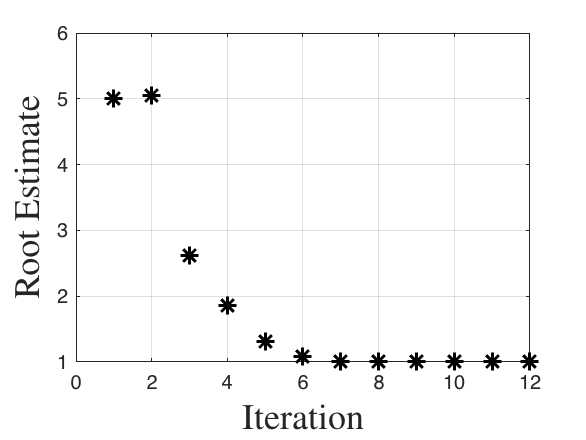

figure;
plot(intermediate_roots,'k*','markersize',9,'linewidth',1.5);
grid on;
xlabel('Iteration','interpreter','latex','fontsize',18);
ylabel('Root Estimate','interpreter','latex','fontsize',18);

We can also extract the converged root from `intermediate_roots`.

root = intermediate_roots(end)

root = 1

## Example #3: Intersection of two curves.

*Find the intersection of *$y=x^2$ and $y=\cos \left(x\right)$ *that is in the interval *$\left\lbrack 0,\infty \right)$.

Defining both functions,

y1 = @(x) x.^2;
y2 = @(x) cos(x);

Let's plot both functions to see where their intersection lies.

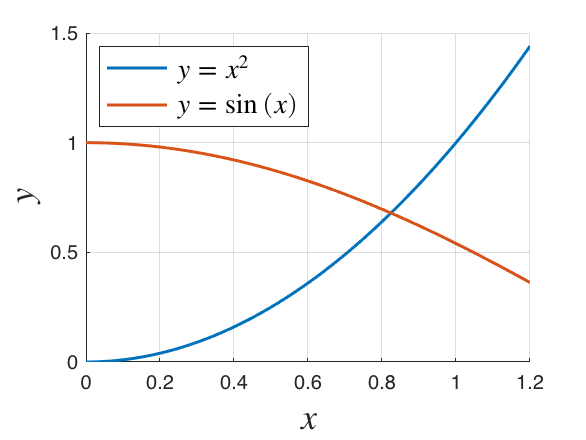

% defines interval for plotting
x = 0:0.01:1.2;

% plot
figure;
hold on;
plot(x,y1(x),'linewidth',1.5);
plot(x,y2(x),'linewidth',1.5);
hold off;
grid on;
xlabel('$x$','interpreter','latex','fontsize',18);
ylabel('$y$','interpreter','latex','fontsize',18);
legend('$y=x^{2}$','$y=\sin{(x)}$','interpreter','latex','fontsize',14,...
    'location','northwest');

Finding the intersection of the two functions is equivalent to finding the *root* of their difference. Therefore, we can use the secant method on $y=\cos \left(x\right)-x^2$ with an initial guess of $x_0 =0\ldotp 8$ (picked using the plot above) to find the intersection.

x_int = secant_method(@(x) y2(x)-y1(x),0.8)

Plotting to confirm that this is the true intersection,

figure;

x_int = 0.8241

hold on;
plot(x,y1(x),'linewidth',1.5);
plot(x,y2(x),'linewidth',1.5);
plot(x_int,y1(x_int),'ko','markersize',9,'linewidth',1.5);
hold off;
grid on;
xlabel('$x$','interpreter','latex','fontsize',18);
ylabel('$y$','interpreter','latex','fontsize',18);
legend('$y=x^{2}$','$y=\sin{(x)}$','intersection','interpreter','latex',...
    'fontsize',14,'location','northwest');

## Example #4: Root of a more complicated function.

*Find all the roots of *$g\left(x\right)$ in the interval $\left\lbrack 0,20\right\rbrack$ where $g\left(x\right)$ is defined using the following calculation procedure:

- 
$$c=5x^2$$


- 
$$d=\sin \left(\frac{c}{500}\right)$$


- 
$$e=\cosh \left(d\right)$$


- 
$$g=5e^2 +27e-40$$


First, we need to define $g\left(x\right)$. **We define **$g\left(x\right)$** as the MATLAB function **$\texttt{gx}$** at the bottom of this page under "gx Function for Example #4".** To define $g\left(x\right)$ as an anonymous function, we assign it a function handle:

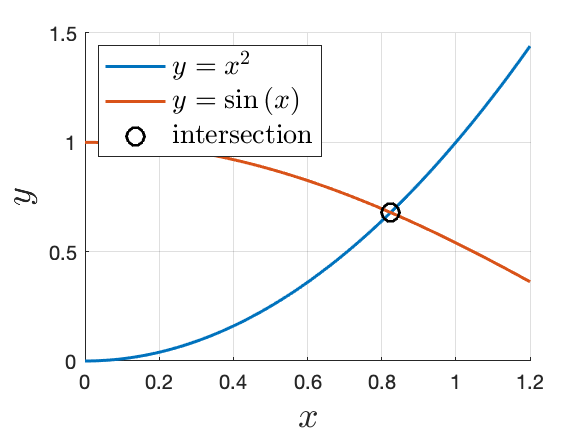

g = @(x) gx(x);

Due to the complexity of $g\left(x\right)$, we have no idea where its root(s) is/are. Therefore, let's first plot $g\left(x\right)$ on $\left\lbrack 0,20\right\rbrack$ (i.e. the interval we want to find the root(s) in).

% interval definition
x = 0:0.1:20;

% evaluates g(x) over interval
g_evaluated = g(x);

% plot of g(x) over the interval [-20,20]
figure;
hold on;
plot(x,g_evaluated,'linewidth',1.5);
plot(x,zeros(size(x)),'k--','linewidth',1.5);
hold off;
grid on;
xlabel('$x$','interpreter','latex','fontsize',18);
ylabel('$g(x)$','interpreter','latex','fontsize',18);

Visually, we can easily identify the following intervals that contain a root:

                    
$$\left\lbrack 8,9\right\rbrack$$


                    
$$\left\lbrack 15,16\right\rbrack$$


                    
$$\left\lbrack 19,20\right\rbrack$$


Solving for the corresponding roots with the secant method, using the midpoints of the above intervals as initial guesses,,

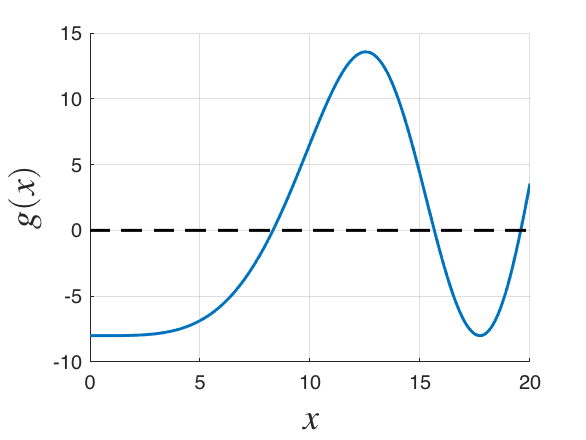

root1 = secant_method(g,8.5)
root2 = secant_method(g,15.5)
root3 = secant_method(g,19.5)

## `gx` Function for Example #4

function g = gx(x)

root1 = 8.3149

    c = 5*x.^2;

root2 = 15.6532

    d = sin(c/500);

root3 = 19.5780

    e = cosh(d);
    g = 5*e.^2+27*e-40;
end